# Equalizer parameters

%Sample frequency
fs = 44100;
% Duration
T = 10;
% Signal (replace with audioread of whatever recording you want)
n = ones(fs*T, 1);

% Equalizer frequency bands and corresponding gain stages
center_freqs =  [63, 125, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 16000];
gains =         [1,    1,   1,   1,   1,    1,    1,    1,    1,    1,     1,     1];

## Normalize and linearize frequency and gain

normalized_freq = [];

for i = 1:length(center_freqs)
    normalized_freq(end+1) = (center_freqs(i)) / (fs / 2) ;
end


linear_gains = 10.^(gains / 20);

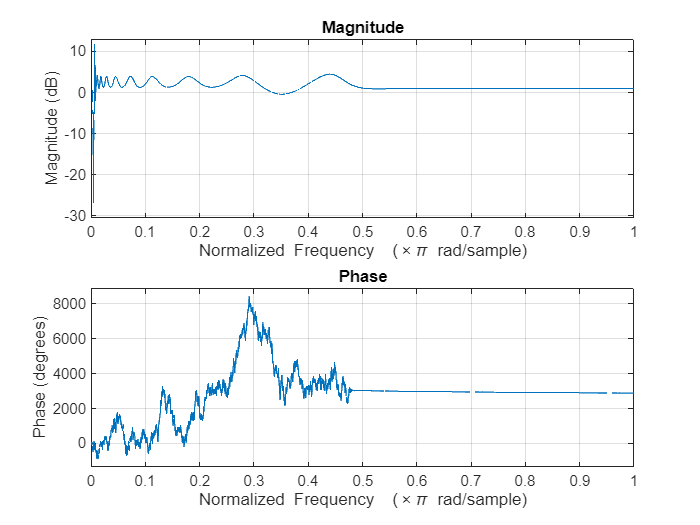

% Apply the filters for each band and their corresponding gain 
% in the ugliest way possible
[b1,a1] = butter(4,normalized_freq(1),'low');
b1 = linear_gains(1) * b1;
[b2,a2] = butter(4,[normalized_freq(1), normalized_freq(2)],"bandpass");
b2 = linear_gains(2) * b2;
[b3,a3] = butter(4,[normalized_freq(2), normalized_freq(3)],"bandpass");
b3 = linear_gains(3) * b3;
[b4,a4] = butter(4,[normalized_freq(3), normalized_freq(4)],"bandpass");
b4 = linear_gains(4) * b4;
[b5,a5] = butter(4,[normalized_freq(4), normalized_freq(5)],"bandpass");
b5 = linear_gains(5) * b5;
[b6,a6] = butter(4,[normalized_freq(5), normalized_freq(6)],"bandpass");
b6 = linear_gains(6) * b6;
[b7,a7] = butter(4,[normalized_freq(6), normalized_freq(7)],"bandpass");
b7 = linear_gains(7) * b7;
[b8,a8] = butter(4,[normalized_freq(7), normalized_freq(8)],"bandpass");
b8 = linear_gains(8) * b8;
[b9,a9] = butter(4,[normalized_freq(8), normalized_freq(9)],"bandpass");
b9 = linear_gains(9) * b9;
[b10,a10] = butter(4,[normalized_freq(9), normalized_freq(10)],"bandpass");
b10 = linear_gains(10) * b10;
[b11,a11] = butter(4,[normalized_freq(10), normalized_freq(11)],"bandpass");
b11 = linear_gains(11) * b11;
[b12,a12] = butter(4,normalized_freq(11),"high");
b12 = linear_gains(12) * b12;

% Create dfilt's for each band
h1 = dfilt.df2t(b1,a1);
h2 = dfilt.df2t(b2,a2);
h3 = dfilt.df2t(b3,a3);
h4 = dfilt.df2t(b4,a4);
h5 = dfilt.df2t(b5,a5);
h6 = dfilt.df2t(b6,a6);
h7 = dfilt.df2t(b7,a7);
h8 = dfilt.df2t(b8,a8);
h9 = dfilt.df2t(b9,a9);
h10 = dfilt.df2t(b10,a10);
h11 = dfilt.df2t(b11,a11);
h12 = dfilt.df2t(b12,a12);

% Use a parallel filterbank because cascading makes the signal way too low
H = dfilt.parallel(h1,h2,h3,h4,h5,h6,h7,h8,h9,h10,h11,h12);


freqz(H)

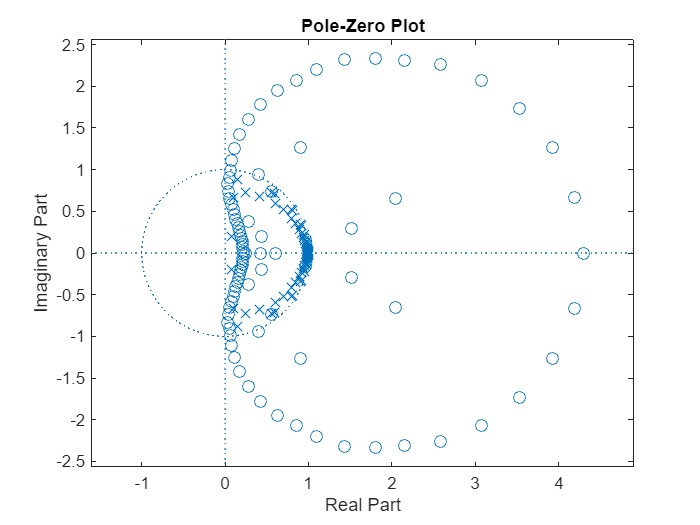

zplane(H)